## Load Measurement Data

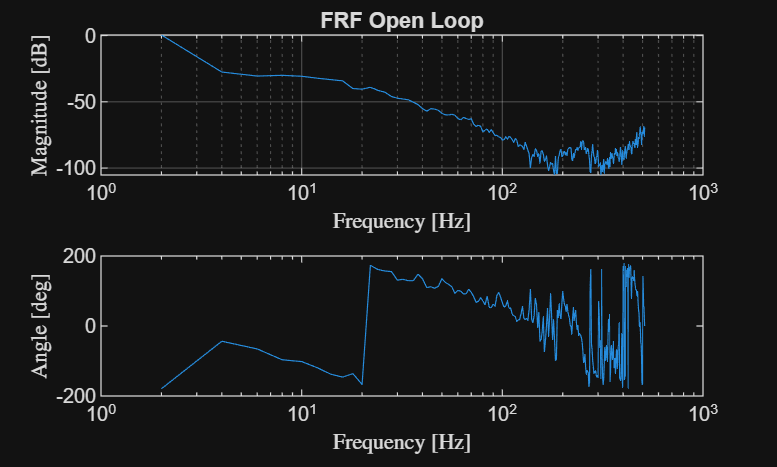

Fig = open("Test_measurements\SUPERNEW_motor3_1024HzSR.fig");
% Extract the relevant data from the opened figure
axesHandles = findobj(Fig, 'Type', 'axes');
dataLines = findobj(axesHandles, 'Type', 'line');
% Assuming we want to extract the X and Y data from the first line object
FRF.f = get(dataLines(1), 'XData');
FRF.mag = get(dataLines(2), 'YData');
FRF.phase = get(dataLines(1), 'YData');

% Plot raw FRF measurement data
figure;
subplot(2,1,1)
semilogx(FRF.f,FRF.mag)
title("FRF Open Loop")
grid on;
xlabel("Frequency [Hz]",Interpreter="latex")
ylabel('Magnitude [dB]',Interpreter="latex")
subplot(2,1,2)
semilogx(FRF.f,FRF.phase)
xlabel("Frequency [Hz]",Interpreter="latex")
ylabel('Angle [deg]',Interpreter="latex")